# ASP

Felber Peter

Example 1

## Special Signals

Special Signals play a crucial role in DSP, they are used to determine the impulse response and support the representation of signals. In this very first task implement the delta-function and the step function as standalone functions.

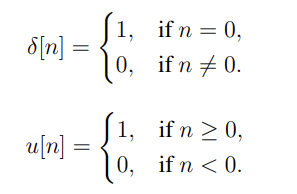

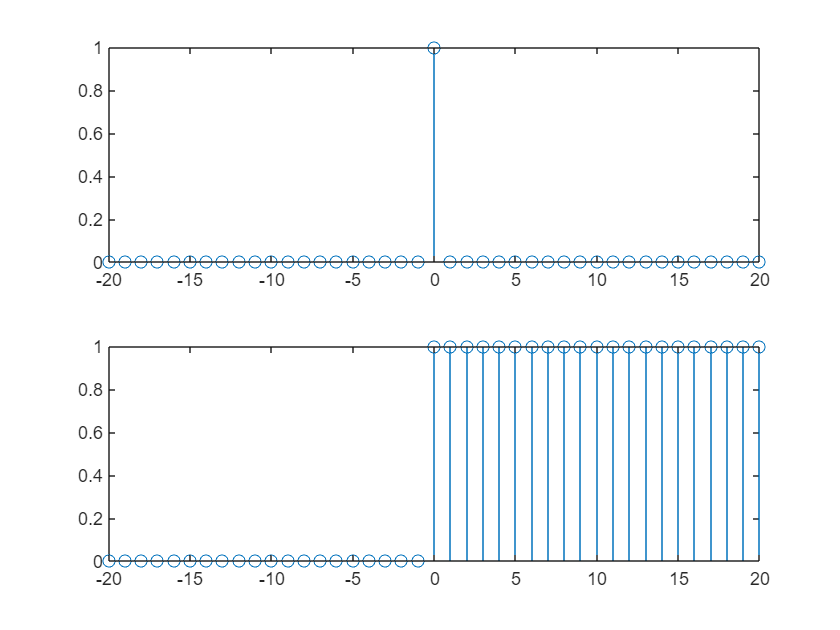

figure;
vn = -20:1:20;
vDelta = Felber.vDeltaFun(vn);
subplot(2,1,1)
stem(vn,vDelta)

vStep = Felber .vStepFun(vn);
subplot(2,1,2)
stem(vn,vStep)

After your implementation test your functions and create and stem the following signals:

(a) δ[n + 1], δ[n − 3] and δ[n + 6]

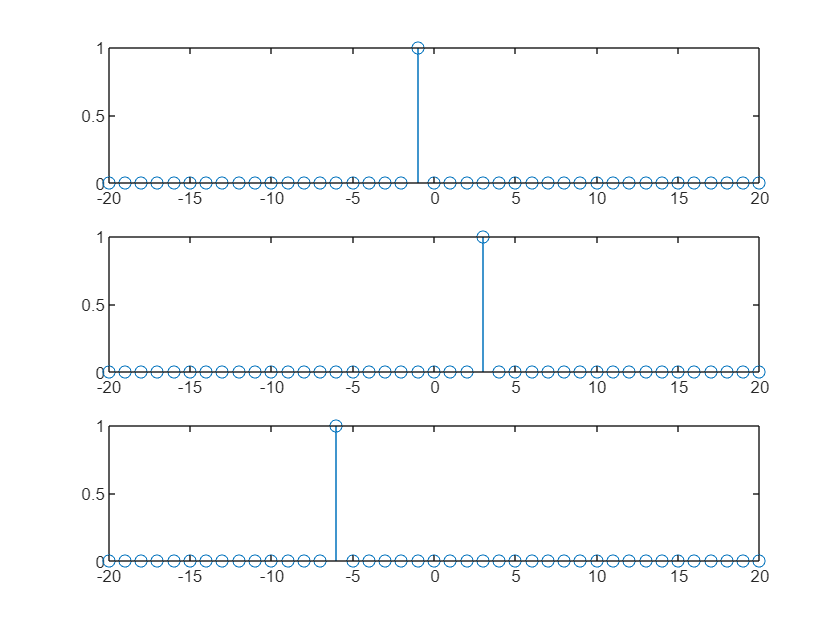

a1Delta = Felber.vDeltaFun(vn+1);
a2Delta = Felber.vDeltaFun(vn-3);
a3Delta = Felber.vDeltaFun(vn+6);

figure
subplot(3,1,1)
stem(vn,a1Delta)
subplot(3,1,2)
stem(vn,a2Delta)
subplot(3,1,3)
stem(vn,a3Delta)

(b) u[n + 5], u[n] and u[n − 3]

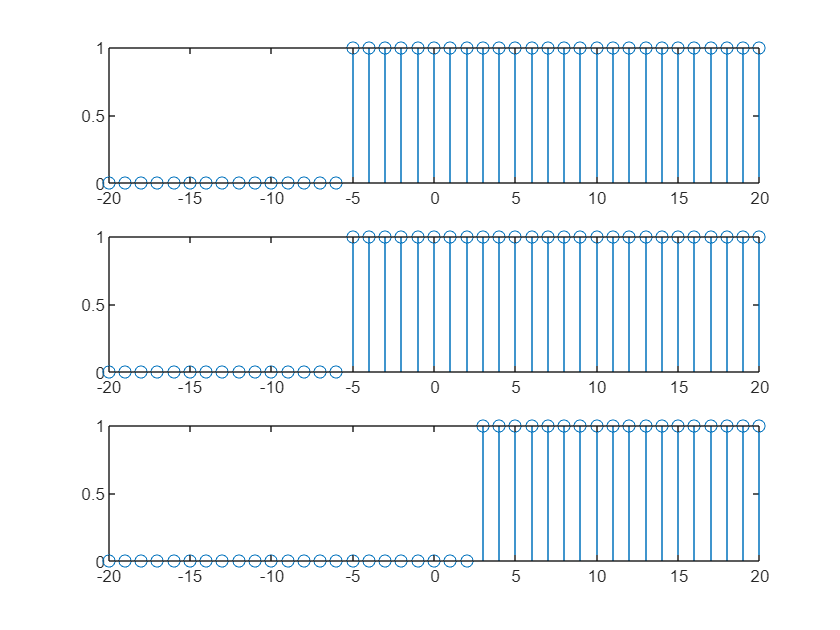

b1Step = Felber.vStepFun(vn+5);
b2Step = Felber.vStepFun(vn+5);
b3Step = Felber.vStepFun(vn-3);

figure
subplot(3,1,1)
stem(vn,b1Step)
subplot(3,1,2)
stem(vn,b2Step)
subplot(3,1,3)
stem(vn,b3Step)

(c) 3δ[n + 1] + n^2 (u[n + 5] − u[n + 4]) + 10(0.5)^n 

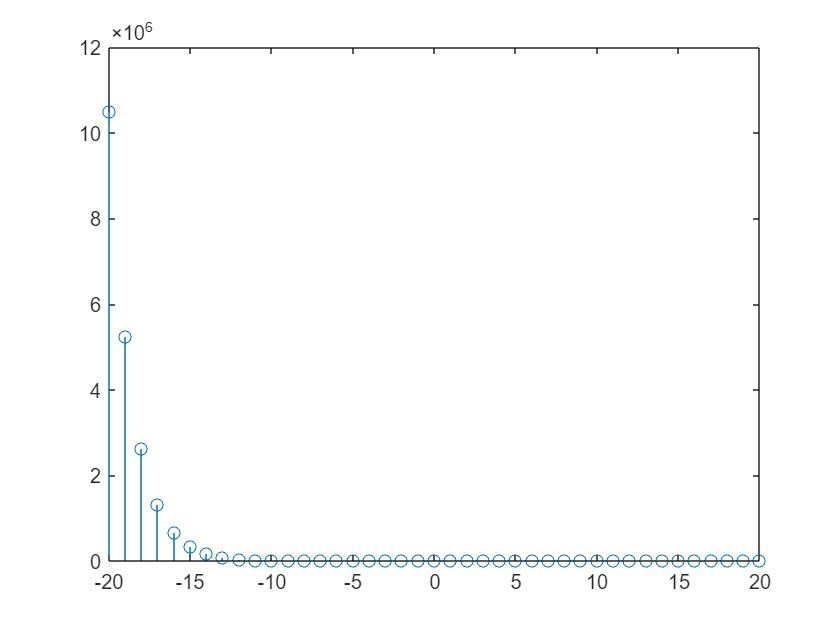

c1DeltaStep = 3 * (Felber.vDeltaFun(vn+1)) + power(vn,2) .* (Felber.vStepFun(vn+5)-Felber.vStepFun(vn+4)) + 10*power(0.5,vn);
figure
stem(vn,c1DeltaStep)

for −20 ≤ n ≤ 20 

Example 2

## Signal modification 

Modify the following signal: 

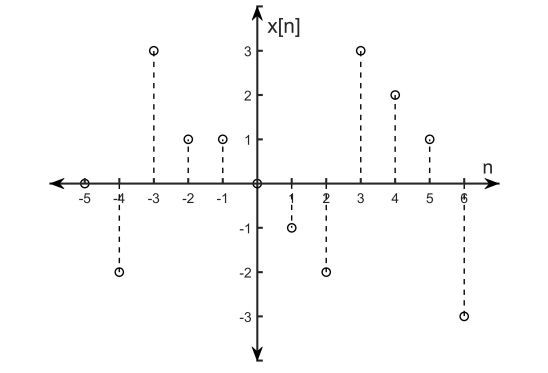

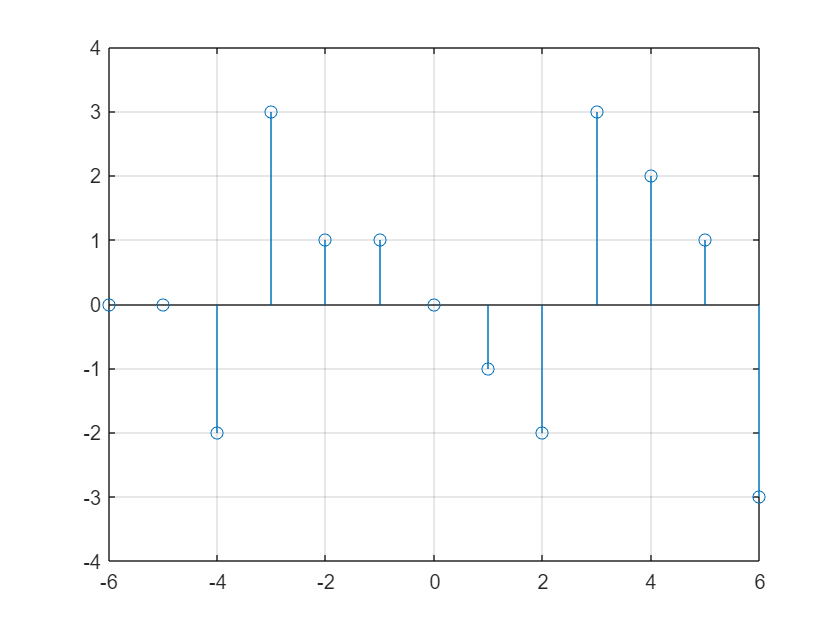

%The signal is made by adding up multible Deltafunktions
Signal2 = -2*Felber.vDeltaFun(vn+4)+3*Felber.vDeltaFun(vn+3)+Felber.vDeltaFun(vn+2)+Felber.vDeltaFun(vn+1)-1*Felber.vDeltaFun(vn-1)-2*Felber.vDeltaFun(vn-2)+3*Felber.vDeltaFun(vn-3)+2*Felber.vDeltaFun(vn-4)+Felber.vDeltaFun(vn-5)-3*Felber.vDeltaFun(vn-6);
stem(vn,Signal2)
grid on
xlim([-6.0 6.0])
ylim([-4.00 4.00])

After your implementation test your functions and create and stem the following signals

%shift flip scale

(a) x[3n + 5] 

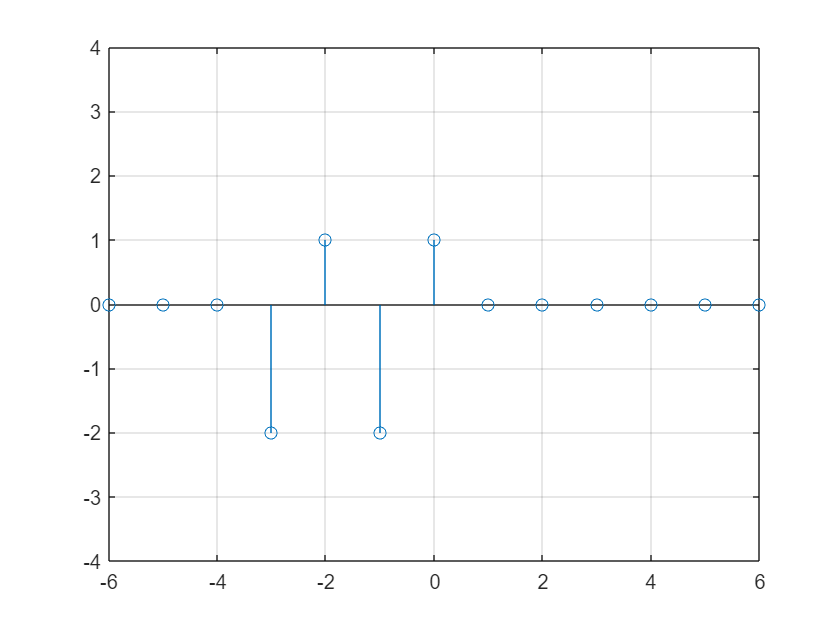

a2 = circshift(Signal2,-5) ;
va2 = vn(3:3:length(vn));
a2 = a2(3:3:length(vn));
stem(va2/3,a2)
grid on
xlim([-6.0 6.0])
ylim([-4.00 4.00])

(b) x[−5n + 4] 

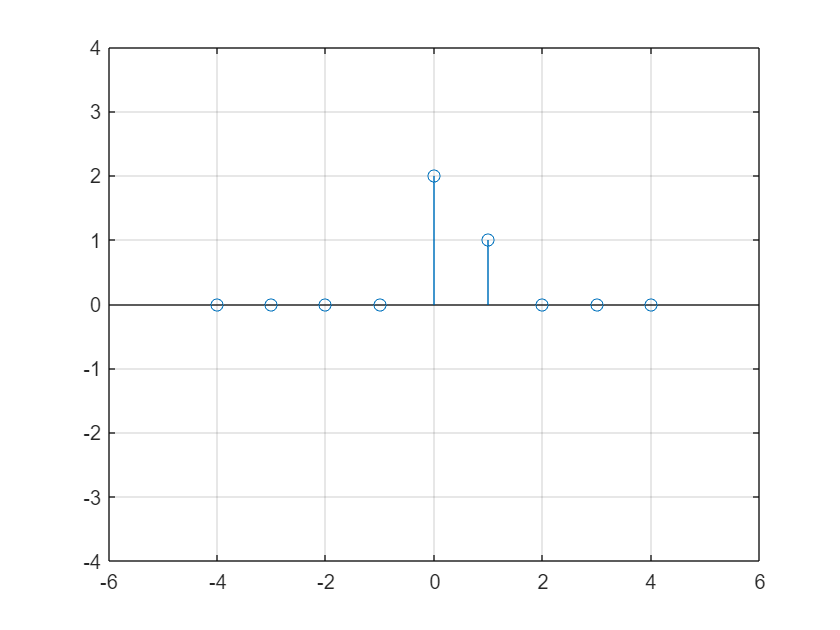

b2 = circshift(Signal2,-4) ;
b2 = fliplr(b2);
vb2 = vn(1:5:length(vn));
b2 = b2(1:5:length(vn));
stem(vb2/5,b2)
grid on
xlim([-6.0 6.0])
ylim([-4.00 4.00])

(c) x[n^2 ] 

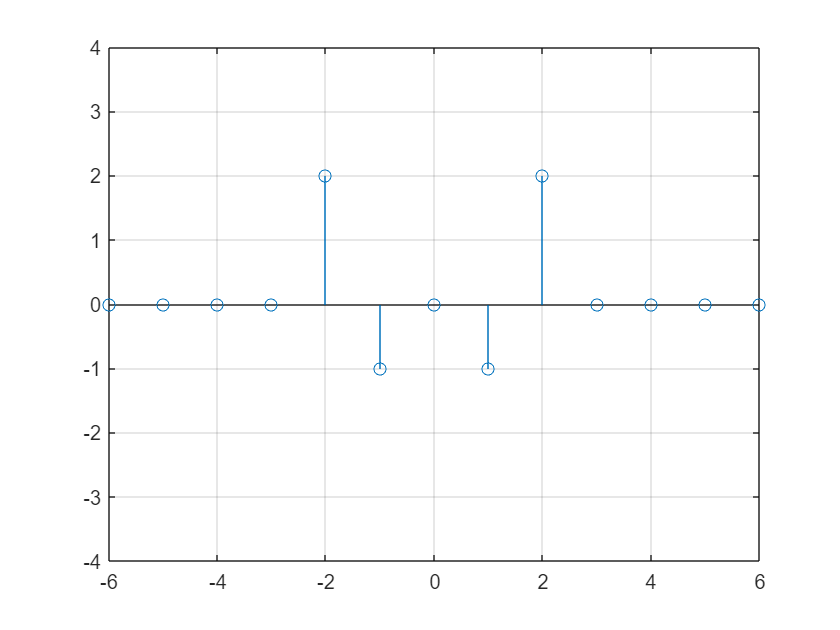

c2 =Mayer.scaleFunc(Signal2,vn,vn.^2) ;
stem(vn,c2)
grid on
xlim([-6.0 6.0])
ylim([-4.00 4.00])

(d) y[n] = x[n] − u[n − 1]x[n − 2] 

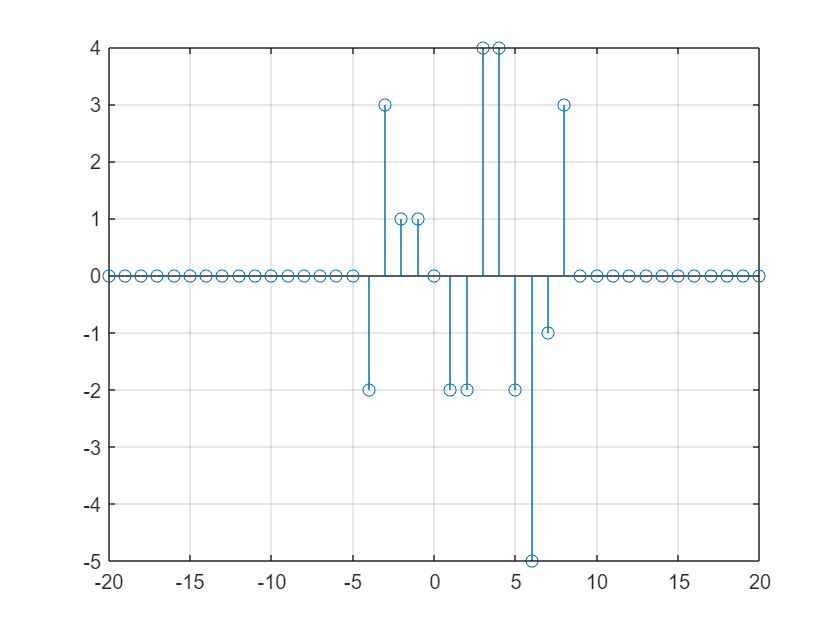

d2 = Signal2-Felber.vStepFun(vn-1).*circshift(Signal2,2);
stem(vn,d2)
grid on

%xlim([-6.0 6.0])
%ylim([-4.00 4.00])

Example 3: 

## Representation of DT Signals

Use the signal x[n] = (−0.2 + j0.3)^n sin(π/4 n)(u[n + 3] − u[n − 5]) for the following tasks. 

Signal3 = (-0.2+1j*0.3).^vn .*sin(pi/4 * vn).*(Felber.vStepFun(vn+3)-Felber.vStepFun(vn-5));

(a) Write a function [vxe,vxo]=analyzeSignal(vn,vx), which calculates the even x_e[n] and the odd x_o[n] part of the signal x[n].

[vxe, vxo] = Felber.analyzeSignal(vn, Signal3);

figure;

% Plot für das ursprüngliche Signal
subplot(3,1,1);
stem(vn, real(Signal3));
title('Original Signal: x[n]');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);  
ylim([-16, 4]); 

% Plot für den geraden Teil
subplot(3,1,2);
stem(vn, vxe);

title('Even Part: x_e[n]');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);   
ylim([-16, 4]);  

% Plot für den ungeraden Teil
subplot(3,1,3);
stem(vn, vxo);

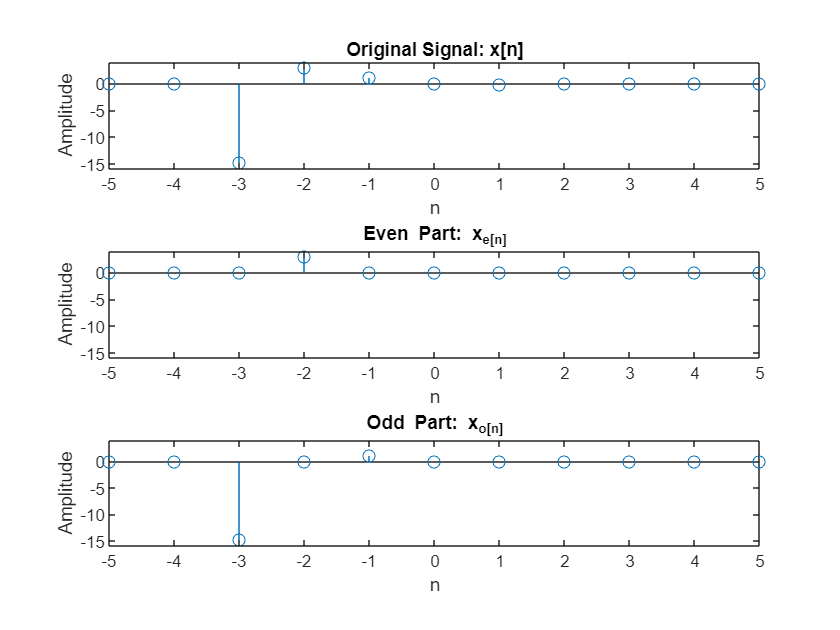

title('Odd Part: x_o[n]');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);  
ylim([-16, 4]); 

(b) Plot the real part and the imaginary part of xe[n]. Does the result agree with your expectations?

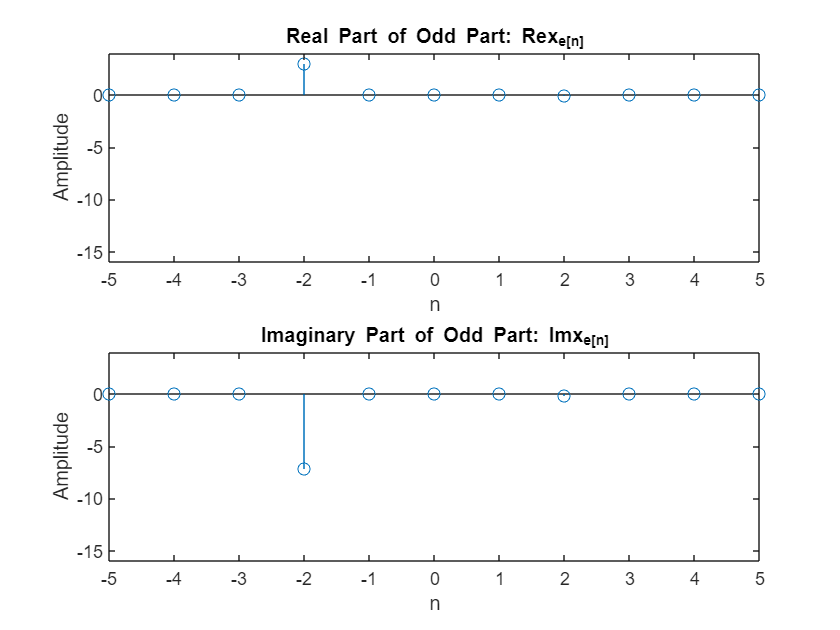

% Plot für den realen Teil von xe[n]
figure;
subplot(2,1,1);
stem(vn, real(vxe));
title('Real Part of Odd Part: Re{x_e[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 

% Plot für den imaginären Teil von xo[n]
subplot(2,1,2);
stem(vn, imag(vxe));
title('Imaginary Part of Odd Part: Im{x_e[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);
ylim([-16, 4]); 

(c) Plot the real part and the imaginary part of xo[n]. Does the result agree with your expectations?

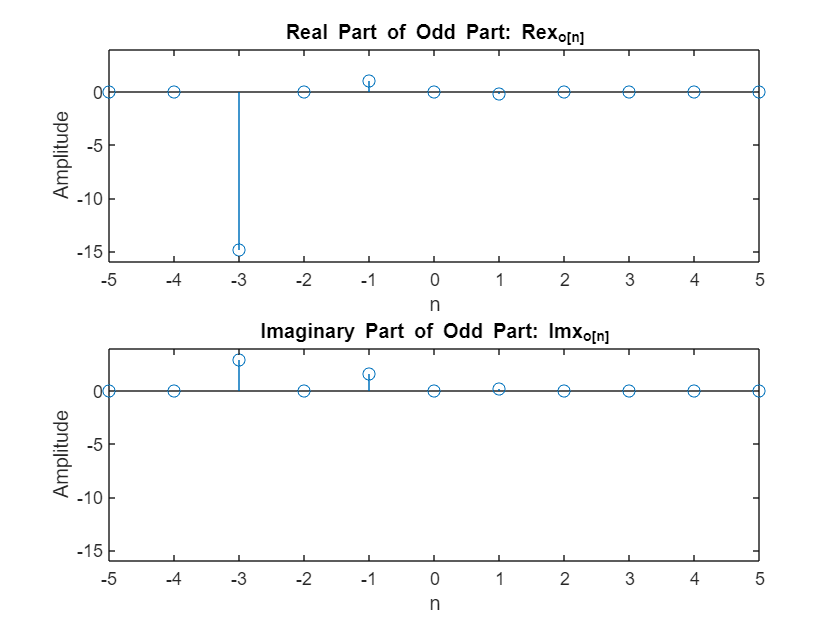

% Plot für den realen Teil von xo[n]
figure;
subplot(2,1,1);
stem(vn, real(vxo));
title('Real Part of Odd Part: Re{x_o[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 

% Plot für den imaginären Teil von xo[n]
subplot(2,1,2);
stem(vn, imag(vxo));
title('Imaginary Part of Odd Part: Im{x_o[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);
ylim([-16, 4]); 

(d) Apply the function analyzeSignal(vn,vx) to the signals xr[n] = ℜ(x[n]) and jxi [n] = jℑ(x[n])

% Signal xr[n]
xr = real(Signal3);

% Signal jxi[n]
jxi = 1i * imag(Signal3);

% Anwendung der Funktion auf xr[n]
[vxe_xr, vxo_xr] = Felber.analyzeSignal(vn, xr);

% Anwendung der Funktion auf jxi[n]
[vxe_jxi, vxo_jxi] = Felber.analyzeSignal(vn, jxi);

(e) Plot the signals xr,e[n] and xr,o[n]. Do the results agree with (b) and (c)? Why or why not?

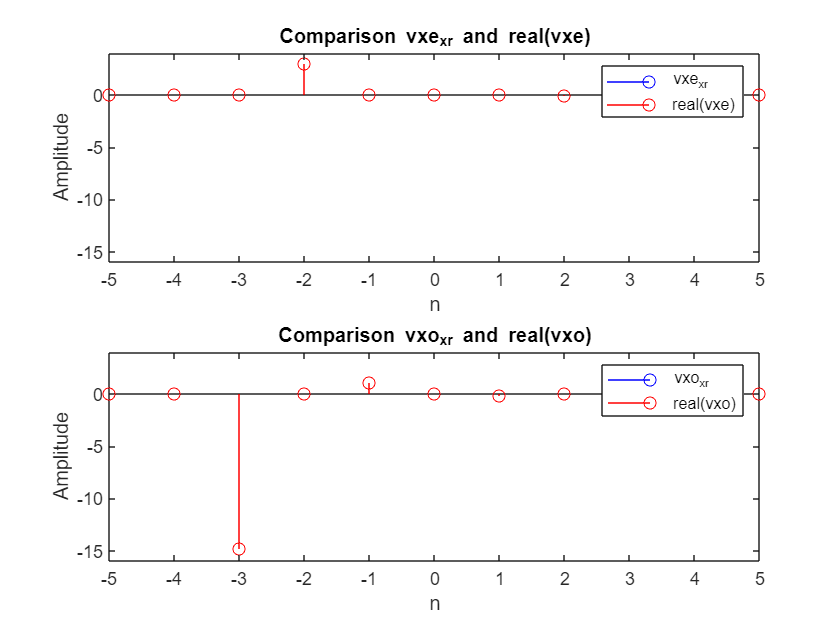

% Vergleich von vxe_xr und real(vxe)
figure;
subplot(2,1,1);
stem(vn, vxe_xr, 'b', 'DisplayName', 'vxe_xr');
hold on;
stem(vn, real(vxe), 'r', 'DisplayName', 'real(vxe)');
hold off;
title('Comparison vxe_xr and real(vxe)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

% Vergleich von vxo_xr und real(vxo)
subplot(2,1,2);
stem(vn, vxo_xr, 'b', 'DisplayName', 'vxo_xr');
hold on;
stem(vn, real(vxo), 'r', 'DisplayName', 'real(vxo)');
hold off;
title('Comparison vxo_xr and real(vxo)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

(f) Plot the signals xi,e[n] and xi,o[n]. Do the results agree with (b) and (c)? Why or why not? 

% Vergleich von vxe_jxi und imag(vxe)
figure;
subplot(2,1,1);
stem(vn, vxe_jxi, 'b', 'DisplayName', 'vxe_jxi');

hold on;
stem(vn, imag(vxe), 'r', 'DisplayName', 'imag(vxe)');
hold off;
title('Comparison vxe_xr and real(vxe)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

% Vergleich von vxo_jxi und imag(vxo)
subplot(2,1,2);
stem(vn, vxo_jxi, 'b', 'DisplayName', 'vxo_jxi');

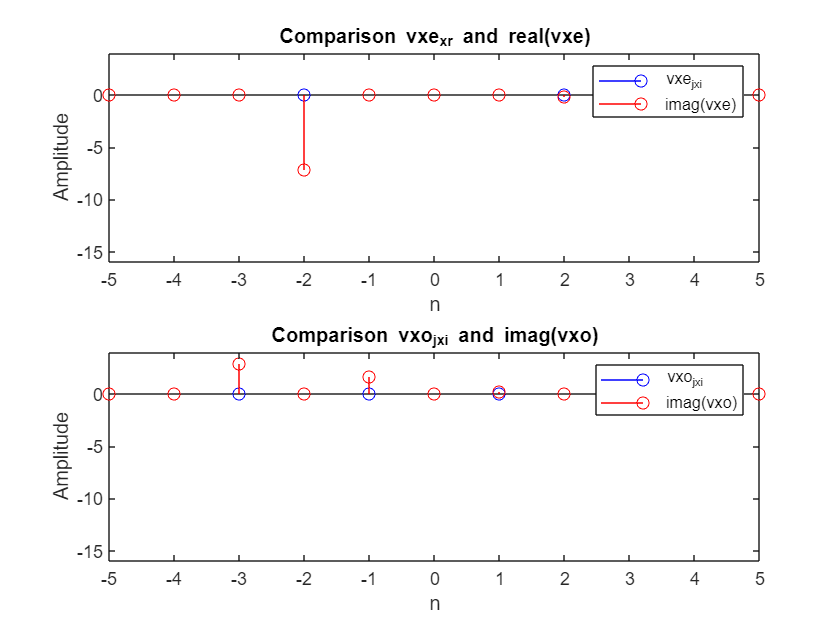

hold on;
stem(vn, imag(vxo), 'r', 'DisplayName', 'imag(vxo)');
hold off;
title('Comparison vxo_jxi and imag(vxo)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

*When plotting the real part of a complex number, only the real component is plotted. *

*However, when applying *`imag()`*, the imaginary part is isolated and treated as a real number, allowing it to be plotted separately.*

Example 4: 

## Convolution

Investigate in the MATLAB functions audioread, sound using MATLAB help

For a given input signal x[n] = [1, 5, −1, 6, 3] and a system output signal y[n] = 3x[n] − 4x[n − 2] + 6x[n − 4] compute the convolution of two vectors:

clc
clear

(a) Determine the impulse respons h[n] of the given system.

h = [3, 0, -4, 0, 6];

(b) Write a function [vconOut] = convASP(vInput1, vInput2), which calculates the convolution of the input vectors. Compare your results with the built-in MATLAB function conv.

% Test the function
x = [1, 5, -1, 6, 3];
y_convASP = Felber.convASP(x, h);

% Compare with MATLAB conv function
y_convMatlab = conv(x, h);

% Check if the results are similar
isequal(y_convASP, y_convMatlab)

ans = logical
   1


(c) Generate the the following impulse response $h_{\textrm{ech}} \left\lbrack n\right\rbrack =\sum_{k=0}^{\infty } \alpha^k \delta \left(n-\textrm{kN}\right)\;$. For α = 0.7 and N = 4 for for −20 ≤ n ≤ 20.

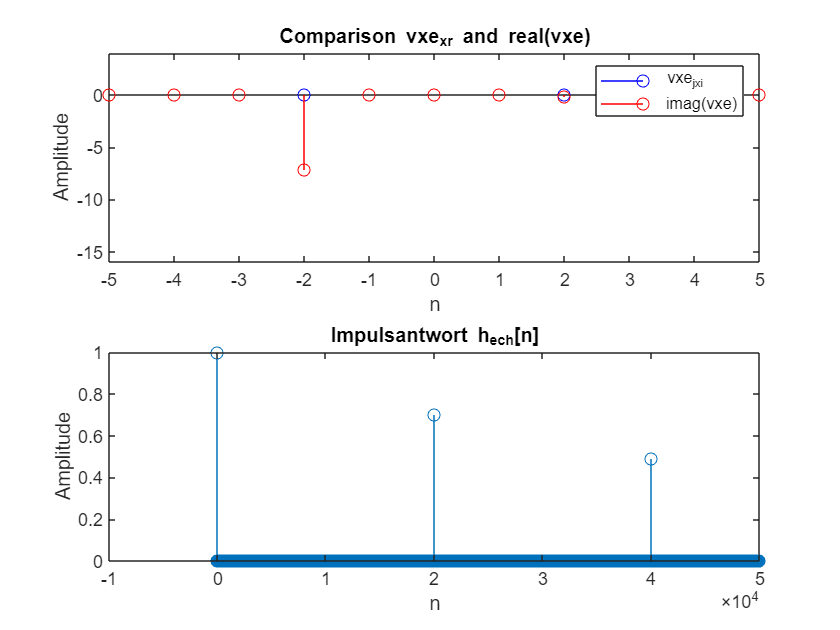

alpha = 0.7;
N = 20000;
n_values = -20:50000;
max_iterations = 2;

h_ech = Felber.calculateImpulseResponse(alpha, N, n_values, max_iterations);

stem(n_values, h_ech);
title('Impulsantwort h_{ech}[n]');
xlabel('n');
ylabel('Amplitude');

(d) Load the audiofile aclarinet.mp3 (Moodle) into your workspace using audioread and compute the convolution with the generated impulse response hech. Set N to a number of samples for one second. Play the result using the MATLAB function sound. What do you notice? After that, set the values α and N to your own desire.

[audio, samplerate] = audioread("+Mayer\sound\sound\meow_cat.wav");
echo = conv(h_ech,audio(:,1),"full");
sound(echo,samplerate)

Example 5: 

## Sounds 

Investigate in the MATLAB functions linspace, sum, sin using MATLAB help 

The creation of signals or sounds is sometimes a great approach to test computed systems or just to have fun. In order to generate oscillating sounds we need to consider the following.

• The sampling frequency fs of a signal let us consider fs = 16384Hz

• A proper duration vector t in order to create time instances for each sample t = [0 : ∆t : T] where the length of t is the duration of the tone multiplied by the number of samples for one second. 

• In order to create an oscillating signal we need an oscillator ω as well. 

(a) Create the following sounds at 440Hz for a sampling frequency fs = 16384Hz with a duration of T = 0.5s:

Sine wave: y(t) = sin(wt)

Square wave: y(t) = ( 0.6, if sin(wt) > 0, 

                                    0, if sin(wt) < 0.

3 sine waves: y(t) = 0.6sin(wt) + 0.3sin(2wt) + 0.1sin(4wt) 

Plot each sound and listen to it, if you want to, using the function sound. How could a triangular wave be implemented? Hint: Use the Fourier JavaApplet to see which cosines and sines, as well as their harmonics, are used to create the signal. 

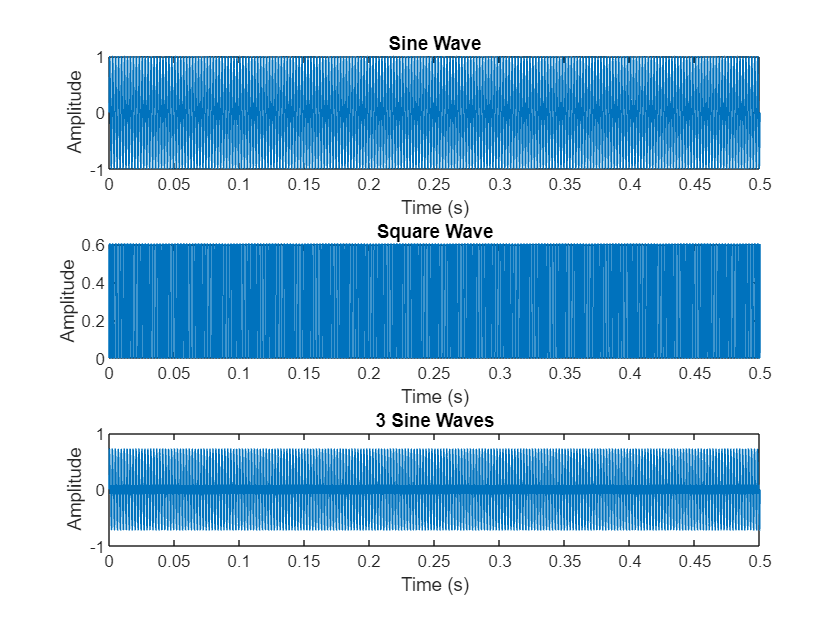

% Parameters
fs = 16384;            % Sampling frequency
T = 0.5;               % Duration in seconds
f = 440;               % Frequency in Hertz
t = linspace(0, T, T * fs);

% Sine wave
y_sine = sin(2 * pi * f * t);

% Square wave
y_square = 0.6 * sin(2 * pi * f * t);
y_square(y_square > 0) = 0.6;
y_square(y_square <= 0) = 0;

% 3 sine waves
y_3sines = 0.6 * sin(2 * pi * f * t) + 0.3 * sin(2 * 2 * pi * f * t) + 0.1 * sin(4 * 2 * pi * f * t);

% Plotting
figure;

subplot(3,1,1);
plot(t, y_sine);
title('Sine Wave');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, y_square);
title('Square Wave');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, y_3sines);
title('3 Sine Waves');
xlabel('Time (s)');
ylabel('Amplitude');


% Listening to the sounds
 sound(y_sine, fs);
 pause(T + 1); 
 sound(y_3sines, fs);
 pause(T + 0.5);
 sound(y_3sines, fs);
 pause(T + 0.5);
 sound(y_3sines, fs);
 pause(T + 0.5);
 sound(y_square, fs);

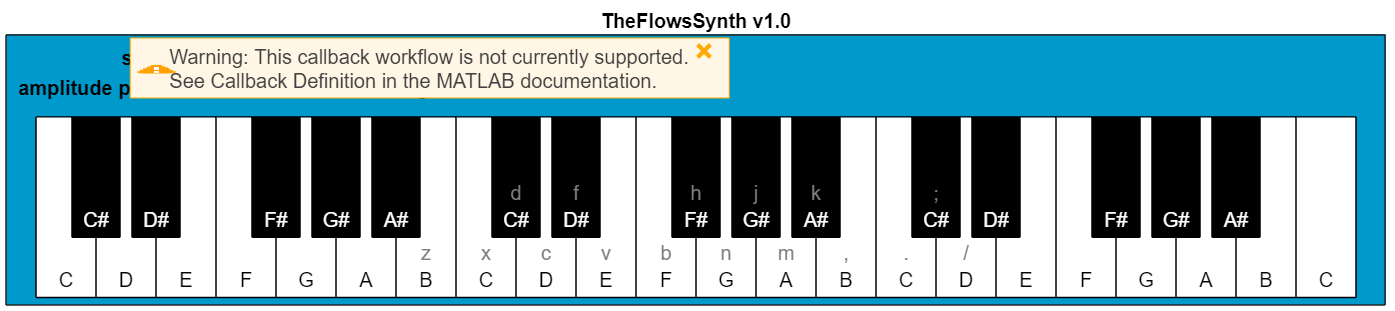

 Mayer.FlowSynth

Example 6: 

## Pre-Processing filter

 clc
 clear

Investigate in the MATLAB functions filter using the MATLAB help

Smoothing is how we discover important patterns in our data while leaving out things that are unimportant (i.e. noise). We use filtering to perform this smoothing. The goal of smoothing is to produce slow changes in value so that it’s easier to see trends in our data

Listing 1: MATLAB built-in test data

 load bostemp
 days = (1:31*24)/24;

(a) The moving average filter is a simple Low Pass FIR (Finite Impulse Response) filter. It takes L samples of input at a time and takes the average of those L-samples and produces a single output point. It is a very simple LPF (Low Pass Filter) structure that comes handy for scientists and engineers to filter unwanted noisy component from the intended data. Create a function myMovingAverage(signal, sampleLength) in order to smooth the measurement results. Adapt and compare your results with the following: 

sampleLength = 10;
MovingAvaragefiltertData = Felber.FilterMovingAvarage(tempC, sampleLength);
myMovingAveragefiltertData = Felber.myMovingAverage(tempC, sampleLength);

(b) Median filters are useful in reducing random noise, especially when the noise amplitude probability density has large tails, and periodic patterns. The median filtering process is accomplished by sliding a window over the image. The filtered image is obtained by placing the median of the values in the input window, at the location of the center of that window. Create a function myMedianFilt(signal, sampleLength) in order to smooth the measurement results.

MedianFiltertData = Felber.myMedianFilt(tempC,sampleLength);

(c) A major advantage of weighted moving averages is that they yield a smoother estimate of the trend-cycle. Instead of observations entering and leaving the calculation at full weight, their weights slowly increase and then slowly decrease, resulting in a smoother curve. Create a function myWeightedMA(signal, sampleLength, weights) in order to smooth the measurement results. It is important that the weights all sum to one and that they are symmetric so that w−k = wk, choose your own weights. Adapt and compare your results with the following:

% Create a weighted moving average using myWeightedMA function
weights = [0.1, 0.2, 0.3, 0.4, 0.5, 0.5 0.4, 0.3, 0.2, 0.1];
smoothedWeightedfiltertData = Felber.myWeightedMA(tempC, sampleLength, weights);
% Create a binomial moving average
h = [1/2 1/2];
binomialCoeff = conv(h, h);
for n = 1:4
    binomialCoeff = conv(binomialCoeff, h);
end
fDelay = (length(binomialCoeff) - 1) / 2;
binomialMAfiltertData = filter(binomialCoeff, 1, tempC);


(d) Compare your implemented filter results, which one fits the best?

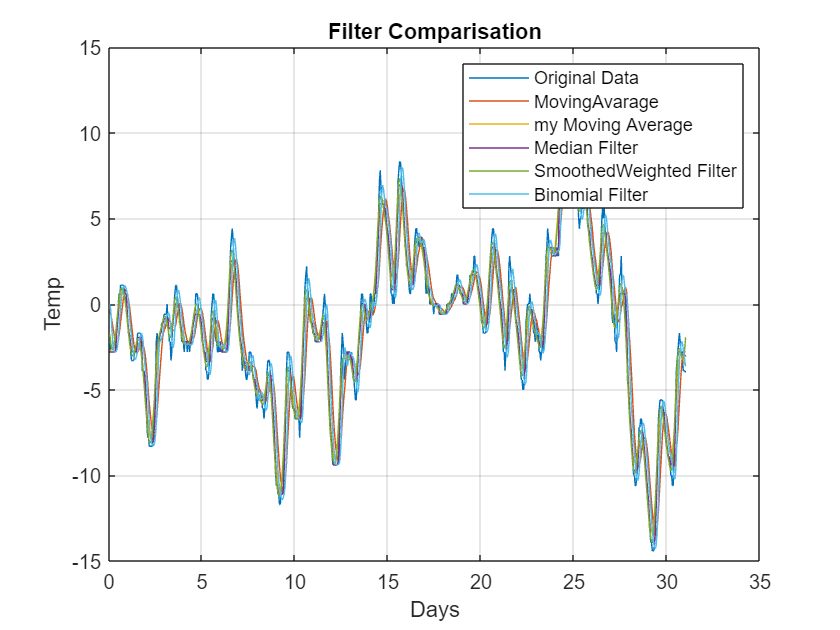

figure;
plot(days, tempC);
hold on;
plot(days, MovingAvaragefiltertData);
plot(days, myMovingAveragefiltertData); 
plot(days,MedianFiltertData);
plot(days,smoothedWeightedfiltertData);
plot(days,binomialMAfiltertData);
title('Filter Comparisation');
legend('Original Data', 'MovingAvarage', 'my Moving Average','Median Filter','SmoothedWeighted Filter','Binomial Filter');
xlabel('Days'); 
ylabel('Temp');
grid on;
hold off;